**Lab 3a**

-----

This simulates the transmission of one resource block between a transmitter and a receiver.

The underlying algorithm uses OFDM to multiplex simultaneous streams of data across multiple channels.

**Theory:**

A resource block represents the data transmitted along multiple carriers across multiple OFDM symbols.

This simulation describes a resource block with 100 channels with 64 symbols per channel.

A given channel might look like:

----

RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE, RE,

1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0

**[0] Setup the Resource Block parameters**

- Lay out the number of blocks

- Lay out the block length

- Determine the appropriate prefix length

block_count  = 1;
block_size = 64;
num_chars = block_size/8;
prefix_length = 16;

**[1] Estimate the channel.**

- Generate some training data across **all** channels

- Average each channel to estimate H_k

- We only want to generate a single block - any more ruins our data

hk = estimate_channel( ...
    1, ...
    block_size, ...
    num_chars, ...
    prefix_length ...
    );

**[2] Generate data**

data_block = transmitter.create_data(...
    block_count, ...
    num_chars...
    );

data_samples = reshape(data_block.', 1, block_size * block_count);

**[3] Encode Data**

encoded_block = transmitter.encode_block(...
    data_block, ...
    prefix_length ...
    );


**[4] Transmit Data through the channel**

[sent_samples, received_samples] = transmitter.transmit( ...
    encoded_block, ...
    prefix_length, ...
    block_count, ...
    num_chars ...
    );

**[5] Correct for any timing issues**

corrected_samples = receiver.time_correction(sent_samples, received_samples);

**[6] Decode the data**

decoded_samples = receiver.decode(corrected_samples, block_count, block_size, prefix_length);

**[7] Equalize the channel**

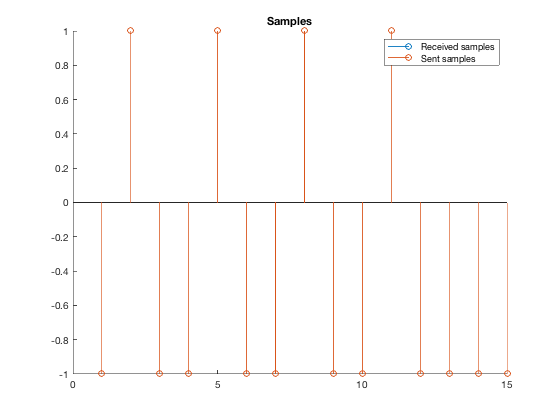

equalized_samples = receiver.equalize_received_samples(decoded_samples, hk, block_count );

num_to_plot = 15;
clf
hold on
title Samples
stem(sign(real(equalized_samples(1:num_to_plot ))))
stem(sign(data_samples(1:num_to_plot )))
legend("Received samples", "Sent samples")
hold off

**[8] Compute Error Rate**

[num_errors, error_rate] = receiver.estimate_error(data_samples, equalized_samples);